# **PCE tunnel  --  Multiple point-Bayesian inferfence**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - ICFEP FE realization ${\mathcal{M}}(r)$

Four FE realization of ICFEP on tunnel 

including G01:G02:101 output settlement point

FE_realization = [294.2	239.1	-0.0014112	-0.0015943	-0.0018151	-0.0020889	-0.0024691	-0.0029583	-0.003559	-0.0042648	-0.0050283	-0.0058767	-0.006823	-0.0078231	-0.0087889	-0.009611	-0.010217	-0.010606	-0.010782	-0.010745	-0.010517	-0.01012	-0.0095827	-0.0089236	-0.0081647	-0.007362	-0.0065442	-0.0057834	-0.0050913	-0.0044809	-0.0039395	-0.003467	-0.0030633
410.9	321.2	-0.0014499	-0.0016211	-0.0018088	-0.0020637	-0.0024259	-0.002918	-0.0035245	-0.004213	-0.0049285	-0.0056697	-0.0064465	-0.0072452	-0.0079743	-0.0085464	-0.0089342	-0.0091634	-0.0092976	-0.0093489	-0.0092584	-0.009013	-0.0086285	-0.00814	-0.0075474	-0.0068876	-0.0061754	-0.0054835	-0.0048187	-0.0042572	-0.0037595	-0.0033257	-0.0029558
416.2	288.4	-0.0014784	-0.0016725	-0.0018827	-0.0021026	-0.0024218	-0.0028406	-0.003346	-0.0039449	-0.0046751	-0.0055379	-0.0065098	-0.0075576	-0.008633	-0.0096185	-0.010406	-0.010914	-0.011074	-0.010938	-0.010595	-0.010114	-0.0095429	-0.0089207	-0.0082342	-0.0074917	-0.0066751	-0.0058833	-0.005141	-0.0044686	-0.0038876	-0.0033982	-0.0030002
444.0	347.3	-0.0012868	-0.0014688	-0.0016809	-0.0019573	-0.0023166	-0.0027732	-0.0033408	-0.0040131	-0.0047697	-0.0056288	-0.0066034	-0.0076689	-0.0088015	-0.0099057	-0.010868	-0.011543	-0.011844	-0.011746	-0.011352	-0.01087	-0.010309	-0.0096558	-0.0088598	-0.0080174	-0.007148	-0.0063138	-0.0055173	-0.0048048	-0.004169	-0.0036101	-0.0031281
557.0	459.8	-0.0015889	-0.0018364	-0.0021002	-0.0024255	-0.0027916	-0.0032293	-0.0037885	-0.0044579	-0.0052722	-0.0062025	-0.0072319	-0.0083264	-0.0094448	-0.010476	-0.011299	-0.011774	-0.011906	-0.01176	-0.011447	-0.011	-0.010459	-0.0097889	-0.0089857	-0.0081457	-0.0073067	-0.0064942	-0.0056923	-0.0050038	-0.004395	-0.0038658	-0.0034164
387.5	380.2	-0.0014364	-0.0016298	-0.001859	-0.0021648	-0.0025495	-0.0030248	-0.0036129	-0.0043119	-0.005106	-0.0060093	-0.0070152	-0.0080887	-0.0091702	-0.01015	-0.010916	-0.011385	-0.011581	-0.011569	-0.011387	-0.011053	-0.010566	-0.0099326	-0.009162	-0.0083359	-0.0074791	-0.006639	-0.0058176	-0.0050826	-0.0044473	-0.0039118	-0.0034759
255.2	202.2	-0.0015249	-0.0017325	-0.0019625	-0.0022462	-0.002604	-0.0030407	-0.0035619	-0.0041518	-0.0048262	-0.0055842	-0.0064144	-0.0072919	-0.0081589	-0.0089243	-0.0095373	-0.0099249	-0.01009	-0.010007	-0.0097462	-0.0093455	-0.008866	-0.0082947	-0.0076549	-0.006975	-0.0062806	-0.0056033	-0.0049519	-0.0043521	-0.0038224	-0.0033627	-0.002973
483.7	371.1	-0.0013963	-0.0015535	-0.0017386	-0.0020148	-0.0024056	-0.0029109	-0.003502	-0.0041795	-0.0049601	-0.0058682	-0.0068953	-0.0080099	-0.0091622	-0.010255	-0.01117	-0.01176	-0.011997	-0.011918	-0.011596	-0.011104	-0.010494	-0.009801	-0.0090145	-0.0081611	-0.0072504	-0.0063716	-0.0055443	-0.0048208	-0.0041824	-0.0036291	-0.0031611
206.1	144.4	-1.47E-03	-1.67E-03	-1.90E-03	-2.21E-03	-2.58E-03	-3.02E-03	-3.55E-03	-4.18E-03	-4.91E-03	-5.72E-03	-6.59E-03	-7.50E-03	-8.39E-03	-9.20E-03	-9.91E-03	-1.04E-02	-1.07E-02	-1.06E-02	-1.04E-02	-1.00E-02	-9.53E-03	-8.93E-03	-8.25E-03	-7.50E-03	-6.72E-03	-5.96E-03	-5.23E-03	-4.60E-03	-4.04E-03	-3.55E-03	-3.15E-03
254.5	222.8	-0.0014905	-0.0017046	-0.0019597	-0.0022643	-0.0026186	-0.0030257	-0.0035244	-0.0041248	-0.0048314	-0.0056375	-0.0065134	-0.0074186	-0.0083005	-0.0091205	-0.0098575	-0.010402	-0.010654	-0.010609	-0.010368	-0.0099795	-0.0094773	-0.008887	-0.0082285	-0.0075407	-0.0068348	-0.0061466	-0.0054751	-0.0048525	-0.0042967	-0.0038077	-0.0033856
303.2	233.1	-0.0015032	-0.0016843	-0.0018944	-0.0021392	-0.0024973	-0.0029633	-0.0035455	-0.0042447	-0.0050416	-0.0059433	-0.0069397	-0.007991	-0.0090289	-0.0099467	-0.010633	-0.011029	-0.011193	-0.011178	-0.01099	-0.010641	-0.010161	-0.0095611	-0.0088056	-0.0079687	-0.0070824	-0.0062325	-0.005433	-0.0047243	-0.0041105	-0.0035915	-0.0031674
382.5	259.5	-0.0014138	-0.0016047	-0.0018294	-0.0020629	-0.002379	-0.002773	-0.0032808	-0.0039146	-0.0046416	-0.0054852	-0.0064416	-0.0074862	-0.0085713	-0.0096073	-0.010492	-0.011124	-0.011492	-0.011589	-0.011408	-0.011018	-0.010408	-0.0096294	-0.0088313	-0.0080167	-0.0071842	-0.0063538	-0.0055463	-0.0048442	-0.0042346	-0.0037175	-0.0032919
432.4	352.6	-0.0014714	-0.0016575	-0.0018531	-0.0020611	-0.0023548	-0.0027605	-0.0032783	-0.0039244	-0.0047118	-0.0056393	-0.0066707	-0.0077615	-0.0088726	-0.0098986	-0.010721	-0.01117	-0.011283	-0.011133	-0.010837	-0.010407	-0.0098528	-0.0092174	-0.0085166	-0.007761	-0.0069818	-0.0062178	-0.0054798	-0.0048084	-0.0042126	-0.0036923	-0.0032478
219.4	153.5	-0.001418	-0.0015983	-0.0018029	-0.0020689	-0.0024054	-0.0028283	-0.00335	-0.0039669	-0.0046793	-0.0054805	-0.0063501	-0.0072463	-0.0081009	-0.0088848	-0.0095941	-0.010204	-0.010635	-0.010853	-0.010812	-0.010484	-0.0098959	-0.0091595	-0.0083413	-0.0075068	-0.0066655	-0.0058684	-0.0051195	-0.0044622	-0.0038976	-0.0034256	-0.0030462
480.6	377.9	-0.0014201	-0.0016242	-0.0018602	-0.0021485	-0.0024932	-0.0029113	-0.0034297	-0.0040583	-0.0048068	-0.0056786	-0.0066585	-0.0077297	-0.0088522	-0.0099277	-0.010835	-0.011398	-0.011636	-0.011536	-0.011224	-0.010718	-0.010122	-0.0094672	-0.0087776	-0.0080332	-0.0072248	-0.0064159	-0.005627	-0.0049174	-0.00428	-0.0037148	-0.0032225
];
size(FE_realization)

ans =     15    33


Plot LHS sampling

LHS_G01 = FE_realization(:,1);
size(LHS_G01)

ans =     15     1


LHS_G02 = FE_realization(:,2);
size(LHS_G02)

ans =     15     1


scatter(LHS_G01,LHS_G02)
xlabel('G01');
ylabel('G02');
title('LHS sampling on G01 and G02')
box on;

plot the FE reliazation 

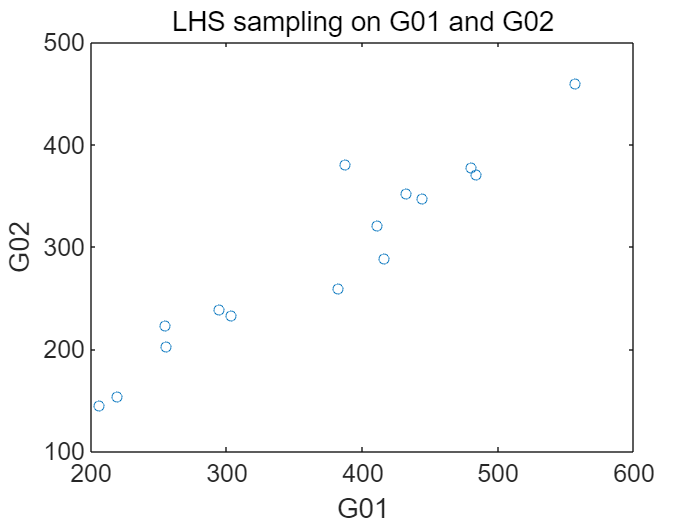

hold off;

X coordinates - FE settlement 

FE_Coordinate= [-2.53E+01	-2.30E+01	-2.06E+01	-1.83E+01	-1.59E+01	-1.36E+01	-1.12E+01	-8.86E+00	-6.51E+00	-4.16E+00	-1.81E+00	5.40E-01	2.90E+00	5.25E+00	7.60E+00	9.95E+00	1.23E+01	1.47E+01	1.70E+01	1.94E+01	2.17E+01	2.41E+01	2.64E+01	2.88E+01	3.11E+01	3.35E+01	3.58E+01	3.82E+01	4.05E+01	4.29E+01	4.52E+01
]';
size(FE_Coordinate)

ans =     31     1


FE_Settlement = FE_realization(:,3:end)';
size(FE_Settlement)

ans =     31    15


FE_Coordinate_Settlement = [FE_Coordinate FE_Settlement];
size(FE_Coordinate_Settlement)

ans =     31    16


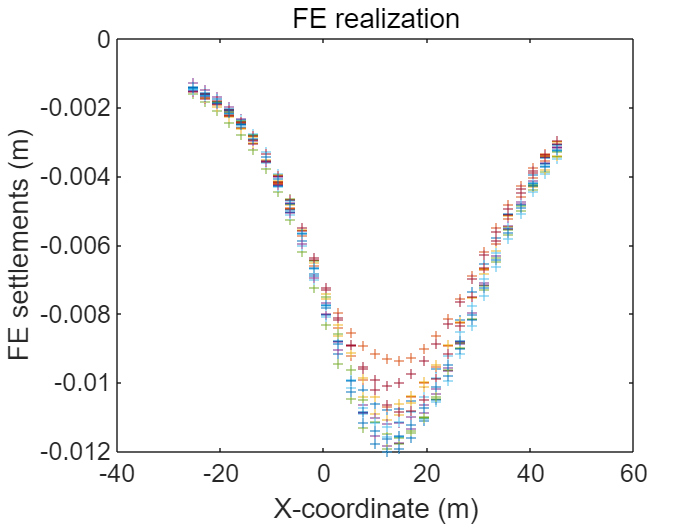


plot(FE_Coordinate_Settlement(:,1),FE_Coordinate_Settlement(:,2:end),'+');
xlabel('X-coordinate (m)');
ylabel("FE settlements (m)");
title('FE realization')

## 3 - PROBABILISTIC INPUT MODEL for PCE

Note: priors for PCE input, not for Bayesian inference prior input

G01 prior for PCE input

InputOpts.Marginals(1).Name = 'G01';
InputOpts.Marginals(1).Type = 'Uniform';
minG01 = min(FE_realization(:,1))

minG01 = 206.1000

maxG01 = max(FE_realization(:,1))

maxG01 = 557

InputOpts.Marginals(1).Parameters  = [minG01 maxG01];

G02 prior for PCE input

InputOpts.Marginals(2).Name = 'G02';
InputOpts.Marginals(2).Type = 'Uniform';
minG02 = min(FE_realization(:,2))

minG02 = 144.4000


maxG02 = max(FE_realization(:,2))

maxG02 = 459.8000


InputOpts.Marginals(2).Parameters  = [minG02 maxG02];

myInput = uq_createInput(InputOpts);

## 4 - Change the Raw measurement  as equal length ---50 settlement points

**X Coordinate + y settlement**

close all;
Raw_Measurement = [-22.7	-0.001293181
-20.2	-0.001483181
-17.7	-0.001773181
-15.2	-0.002293181
-12.7	-0.002693181
-10.21	-0.003353181
-10.22	-0.003443181
-7.7	-0.004203181
-5.2	-0.005043181
-2.7	-0.006253181
-0.2	-0.007383181
2.3	-0.008663181
4.8	-0.010223181
12.5	-0.013313181
15	-0.013713181
17.5	-0.013773181
20	-0.013153181
22.5	-0.012233181
25	-0.010903181
27.5	-0.009483181
46.15	-0.002233181
];
size(Raw_Measurement)

ans =     21     2


X_Raw_Measurement = Raw_Measurement(:,1);
size(X_Raw_Measurement)

ans =     21     1


Y_Raw_Measurement = Raw_Measurement(:,2);
size(Y_Raw_Measurement)

ans =     21     1


%fitting
%split the range into 50 points
Xmin = min(X_Raw_Measurement)

Xmin = -22.7000

Xmax = max(X_Raw_Measurement)

Xmax = 46.1500

X_Equal_length = linspace(Xmin,Xmax,30)';
size(X_Equal_length)

ans =     30     1


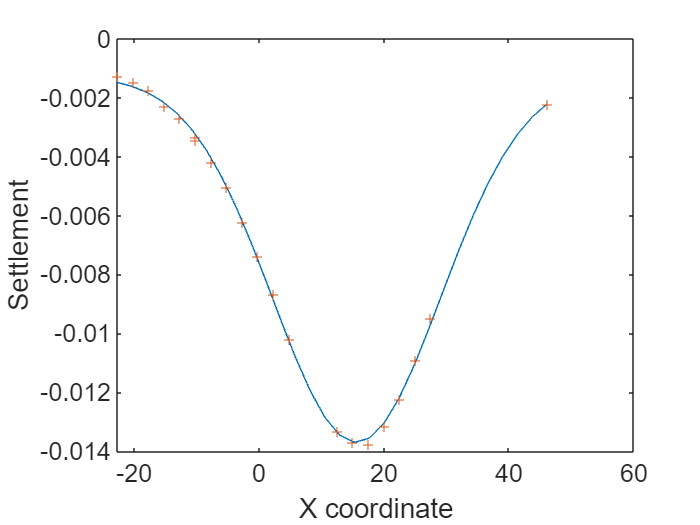

% Y_Equal_length_Measurement = interp1(X_Raw_Measurement,Y_Raw_Measurement,X_Equal_length);
% size(Y_Equal_length_Measurement)
% %plotting
% plot(X_Raw_Measurement,Y_Raw_Measurement,'+');
% hold on;
% plot(X_Equal_length,Y_Equal_length_Measurement);
% xlabel('Measurement X distance')
% ylabel('Measurement settlement(m)')
% hold off;
%Gaussian fitting 
func = fittype('a*exp(-((x-b)/c)^2)+d');

%Four start point

startpoint = linspace(Xmin,Xmax,4);

[cf,gof] = fit(X_Raw_Measurement,Y_Raw_Measurement,func,'Start',startpoint); 
Y_Equal_length_Measurement = cf.a*exp( -((X_Equal_length-cf.b)/cf.c).^2)+cf.d; 
hold on;
plot(X_Equal_length,Y_Equal_length_Measurement);
plot(X_Raw_Measurement,Y_Raw_Measurement,'+');
hold off;
box on;
xlabel('X coordinate');
ylabel('Settlement');

## 5 Change the FE outpout size equal length---50 settlement points

close all;
N_FE_realization = size(FE_realization,1)

N_FE_realization = 15

size(FE_Coordinate_Settlement)

ans =     31    16


FE_Equal_length = [];

Loop to get the new  equal length FE output 

for i = 1: N_FE_realization
    %hold on;
    %fitting %interpolation

    X_FE = FE_Coordinate_Settlement(:,1);
    Y_FE = FE_Coordinate_Settlement(:,i+1);   
    startpoint = linspace(min(X_FE),max(X_FE),4); 
    
    
    [cf,gof] = fit(X_FE,Y_FE,func,'Start',startpoint); 
    
    Y_FE_Equal_length = cf.a*exp( -((X_Equal_length-cf.b)/cf.c).^2)+cf.d; 
    FE_Equal_length = [FE_Equal_length Y_FE_Equal_length];

end
%plotting
close all;
plot(FE_Coordinate_Settlement(:,1),FE_Coordinate_Settlement(:,2:end),'+');
hold on;
plot(X_Equal_length,FE_Equal_length);
xlabel('FE X distance')
ylabel('FE settlement(m)')

Put the measurements into the figure and have a look

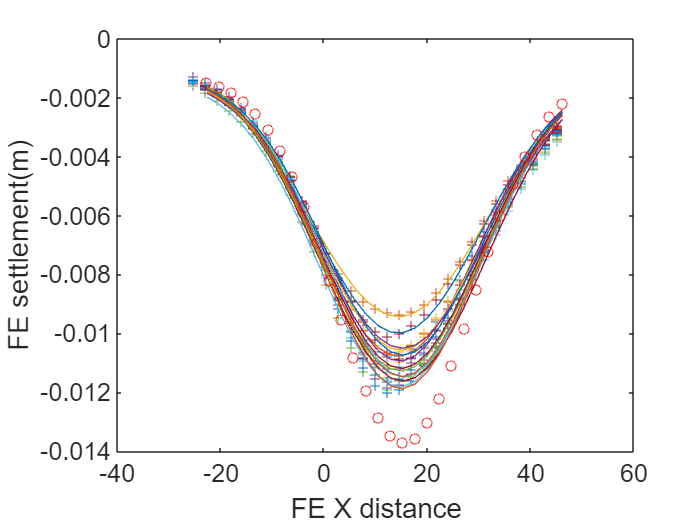

hold on;
plot(X_Equal_length,Y_Equal_length_Measurement,'o',Color='red');
hold off;

## 6 PCA reduce output dimensionality

%get the FE output

Y_Output = FE_Equal_length';
size(Y_Output)

PCA reduction 

[V,S,E,cumE,number]=princa(Y_Output,0.99)
save S;
save V;
save number;
save st;
save mv;

PCA reconstruct

%reconstruct the output
[m, n] = size(S);  % calculate the rows and coloums of X
mv = mean(Y_Output);  % calculate the mean of X
st = std(Y_Output);   %calculate the standard diviation of X

Y_ouput_reconstructed = S(:, 1:number) * V(:, 1:number)';
%De-normalize the score for each principal component
for i = 1:size(Y_ouput_reconstructed, 2)
    Y_ouput_reconstructed(:, i) = Y_ouput_reconstructed(:, i) * st(i) + mv(i);
end

size(Y_ouput_reconstructed)

modelling error of PCA truncation

PCA_loss =abs(Y_Output - Y_ouput_reconstructed);
size(PCA_loss)
Cov_PCA_loss = cov(PCA_loss);
size(Cov_PCA_loss)
h = heatmap(Cov_PCA_loss)
h.FontSize = 10
xlabel('Data Component');
ylabel('Data component');
% orignal xy label
xLabels = h.XDisplayLabels;
yLabels = h.YDisplayLabels;

% ticks for 10  20 30
xLabelsToShow = cell(size(xLabels));
yLabelsToShow = cell(size(yLabels));

for i = 1:length(xLabels)
    if ismember(str2num(xLabels{i}), [10, 20, 30])
        xLabelsToShow{i} = xLabels{i};
    else
        xLabelsToShow{i} = '';
    end
end

for j = 1:length(yLabels)
    if ismember(str2num(yLabels{j}), [10, 20, 30])
        yLabelsToShow{j} = yLabels{j};
    else
        yLabelsToShow{j} = '';
    end
end

% x-y label
h.XDisplayLabels = xLabelsToShow;
h.YDisplayLabels = yLabelsToShow;
h.Colormap = parula

## 7 - POLYNOMIAL CHAOS EXPANSION (PCE) METAMODELS $\tilde{\mathcal{M}}(r)$

Calculate the polynomial chaos expansion (PCE) coefficients.

Select PCE as the metamodeling tool in UQLab:

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the LARS for the PCE coefficients calculation strategy:

Specify the sparse truncation scheme (hyperbolic norm with ):

metaopts.Method = 'LARS';
metaopts.TruncOptions.qNorm = 0.75;

Select the PCE options and create the PCE model:

metaopts.Degree = 2:15;

Experimental design (Note: PCE on Pricinple component of Y outputs, not on Y outputs)

X = FE_realization(:,1:2);
size(X)
%Y = FE_Equal_length';
Y = S(:, 1:number);
size(Y)
metaopts.ExpDesign.X = X;
metaopts.ExpDesign.Y = Y;

Calculation

myPCE = uq_createModel(metaopts);

Print a summary of the resulting PCE metamodel:

N_PCE = size(Y,2);
uq_print(myPCE, [1:N_PCE])

Export the PCE strucuture

save myPCE

## 8 - Yval vs YPCE 

Create a validation sample of size  from the input model:

Xval =  FE_realization(:,1:2);
size(Xval)

Evaluate the full model response at the validation sample points:

Yval =  FE_Equal_length';
size(Yval)

Responses for PCE 

% Obtain the principle components of Y output
YPCE= uq_evalModel(myPCE,Xval);

% %reconstruct the output

YPCE = S(:, 1:number) * V(:, 1:number)';
% De-normalize the score for each principal component
for i = 1:size(YPCE, 2)
    YPCE(:, i) = YPCE(:, i) * st(i) + mv(i);
end


True vs predicted plot (Note: plot on the full order Y output, not on the PCs)

close all;
uq_figure

hold on
uq_plot([min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')], 'k')

axis equal
axis([[min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')]])
uq_plot(Yval, YPCE, '+')
xlabel('Yval');
ylabel('YPCE');
box on;
hold off;

modelling error of PCE truncation

PCE_loss =abs(Yval - YPCE);
size(PCE_loss)
Cov_PCE_loss = cov(PCE_loss);
size(Cov_PCE_loss)
heatmap(Cov_PCE_loss)

## 9 - Define the priors for G01/G02 and discrepancy $\sigma$ for Bayesian inference

## **Note: priors for **G01/G02** are different from input models above**

By default, UQlab assumes an independent and identically distributed discrepancy

$G_{01} \sim \mathcal{N}(500,150)$;$G_{02} \sim \mathcal{N}(300,100)$

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

 priors

%Priors on G01 , G02 and sigma

%prior on G01
PriorOpts.Marginals(1).Name = 'G01';               
PriorOpts.Marginals(1).Type = 'Gaussian';
PriorOpts.Marginals(1).Moments   = [500 150];   
PriorOpts.Marginals(1).Bounds = [100 900];

%prior on G02
PriorOpts.Marginals(2).Name = 'G02';              
PriorOpts.Marginals(2).Type = 'Gaussian';
PriorOpts.Marginals(2).Moments   = [300 100];   
PriorOpts.Marginals(2).Bounds = [100 500];

%prior on Sigma2
PriorOpts.Marginals(3).Name = 'sigma2';              
PriorOpts.Marginals(3).Type = 'Uniform';
sigma2 = mean(Raw_Measurement(:,2),"all")
PriorOpts.Marginals(3).Parameters = [0 sigma2.^2];



myPriorDist = uq_createInput(PriorOpts);


## 10 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$\ell\mathcal{L} ({\vec{\theta}},{\epsilon} \mid {Y}) = \prod_{i=1}^{N}\frac{1}{(2\pi)^{{3}/2}\det({\Sigma}(\epsilon))^{1/2}}\exp\left(-\frac{1}{2}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)^{{T}} {\Sigma}(\epsilon)^{-1}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)\right)$$


myData.y = Y_Equal_length_Measurement';
size(myData.y)
myData.Name = 'Settlement along the tunnel';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) myLogLikeli2(params,y);

## 11 - Solver options

Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2 3];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 1000;
Solver.MCMC.NChains = 20;
%myProposal.PriorScale = 0.001;

## 12 - Bayesian inference

%BayesOpts.Discrepancy = DiscrepancyOptsUnknownDisc;
%BayesOpts.ForwardModel.Model = myPCE;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

## 13 - Post-processing

Burn in 70%; 


uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','MAP','percentiles',[0.05,0.95],'burnin',0.7);

uq_print(BayesAnalysis);
%uq_postProcessInversion(BayesAnalysis,'priorPredictive',1000);
uq_display(BayesAnalysis);

## 14 -  Sampling for G01 and G02 (90%CI)

set 90%CI  = 95%- 5%

close all;
uq_postProcessInversionMCMC(BayesAnalysis,'percentiles',[0.05,0.95]);

Obtained the lower bound and upper bound for G01 and G02

G01_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,1);
display(G01_5_LowB)

G01_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,1);
display(G01_95_UpperB)
G02_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,2);
display(G02_5_LowB)

G02_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,2);
display(G02_95_UpperB)
N_predict = 100

% sampling on G01
G01_90_sample_O = linspace(G01_5_LowB,G01_95_UpperB,N_predict)';
size(G01_90_sample_O)

%Shuffle the order 
shuffledIndices = randperm(length(G01_90_sample_O));
G01_90_sample = G01_90_sample_O(shuffledIndices);
size(G01_90_sample)
% sampling on G02
G02_90_sample_O = linspace(G02_5_LowB,G02_95_UpperB,N_predict)';
size(G02_90_sample_O)
%Shuffle the order 
shuffledIndices = randperm(length(G02_90_sample_O));
G02_90_sample = G02_90_sample_O(shuffledIndices);
size(G02_90_sample)
%plot the sampling on G01 and G02 
figure
plot(G01_90_sample,G02_90_sample,'*');
xlabel('G01');
ylabel('G02');

axis([min(G01_90_sample,[],'all') max(G01_90_sample,[],'all') min(G02_90_sample,[],'all') max(G02_90_sample,[],'all')])

## 14 - 90%  error band

close all;

Predictive FE realization

Predict_sample = [G01_90_sample,G02_90_sample];
size(Predict_sample)

%Loop to get the predictive FE deflection

YPCE_Predict = [];

for i = 1:N_predict
    
    Xval_Predict = Predict_sample(i,:);   

    Deflection = uq_evalModel(myPCE,Xval_Predict);
    YPCE_Predict = [YPCE_Predict;Deflection];


end

size(YPCE_Predict)


 
% %reconstruct the output

YPCE_Predict = YPCE_Predict * V(:, 1:number)';
% 逆标准化每个主成分的得分
for i = 1:size(YPCE_Predict, 2)
    YPCE_Predict(:, i) = YPCE_Predict(:, i) * st(i) + mv(i);
end


Spline curve fitting to smooth the line for the 90CI


for i = 1:size(YPCE_Predict,1)
    
    xi = min(X_Equal_length):0.5:max(X_Equal_length);

    YPCE_Predict_Poly(i,:) = interp1(X_Equal_length',YPCE_Predict(i,:),xi);
end
size(YPCE_Predict_Poly)

Loop to fill the error band 90%CI

%loop to fill the error band

for i = 1:size(YPCE_Predict_Poly,1)-1
    hold on;
    fill([xi fliplr(xi)], [YPCE_Predict_Poly(i,:) fliplr(YPCE_Predict_Poly(i+1,:))], 'cyan', 'FaceAlpha', 1,'EdgeColor','none');
end

 hold on;
 
 xlabel('Distance \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Settlement (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
 %ylim([-3.5 0])

scatter the measurement

for i = 1: size(myData.y,1)
    scatter(X_Equal_length,myData.y(i,:),'black','x');
    hold on;
end

draw the mean value of 90%CI

plot(xi,mean(YPCE_Predict_Poly),'red','LineWidth',1.5);